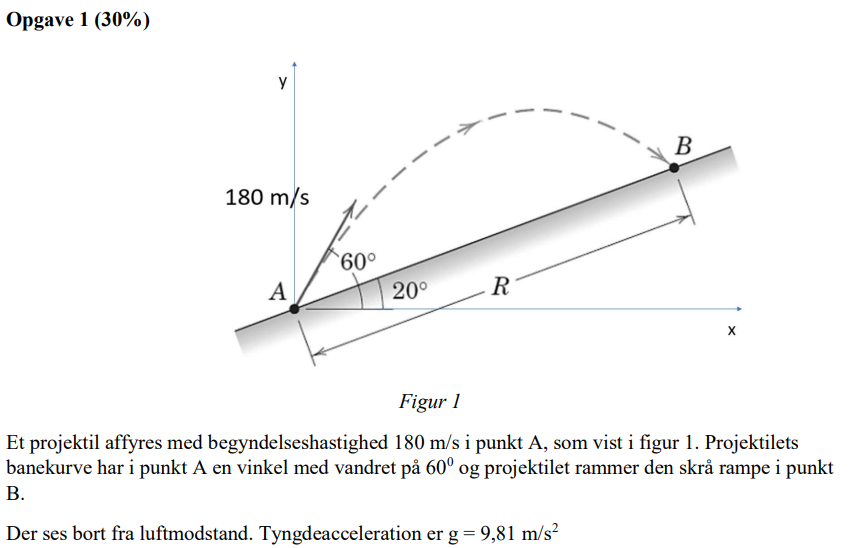

v_0 = 180;
theta = deg2rad(60);
g = 9.81;
v_x = v_0 * cos(theta)

v_x = 90.0000

v_y = v_0 * sin(theta)

v_y = 155.8846

## A) Den lodrette afstand $y_{max}$ fra A til banekurvens toppunkt

Den største lodrette afstand $y_{max}$ kan bestemmes gennem følgende ligning:

- 
$$y_{max} = \frac{v^2 - v_0^2}{2 \cdot a} \equiv \frac{0.5 \cdot v_y^2}{g} = 1601.58 m$$


y_maks = vpa((0.5*v_y^2)/(g),6)

$$y\_maks = 1238.53$$

## B) Forskriften y(x) for projektilets banekurve, i det viste koordinatsystem. y(x) og den skrå rampe ønskes plottet i samme koordinatsystem

Funktions forskriften for $y(x)$ kan defineres som:

- 
$$x = v_0 \cdot cos(\theta) \cdot t \rightarrow t = \frac{x}{v_x}$$


Hvoraf afstandsforskriften for y ser ud som følgende:

- 
$$y(t) = y_0 + v_0 \cdot t - \frac{1}{2} \cdot g \cdot t^2

\rightarrow

y(x) = y_0 + v_y \cdot \frac{x}{v_x} - \frac{1}{2} \cdot g \cdot (\frac{x}{v_x})^2$$


Plottet dannes på baggrund af den reelle afstands for og hældningen for rampen:

- 
$$y(x) = y_0 + v_y \cdot \frac{x}{v_x} - \frac{1}{2} \cdot g \cdot (\frac{x}{v_x})^2 \equiv y(x) = 1.73 \cdot x - 6.06 \cdot 10^{-4} \cdot x^2$$


- 
$$y_{rampe} = x \cdot tan(\theta)$$


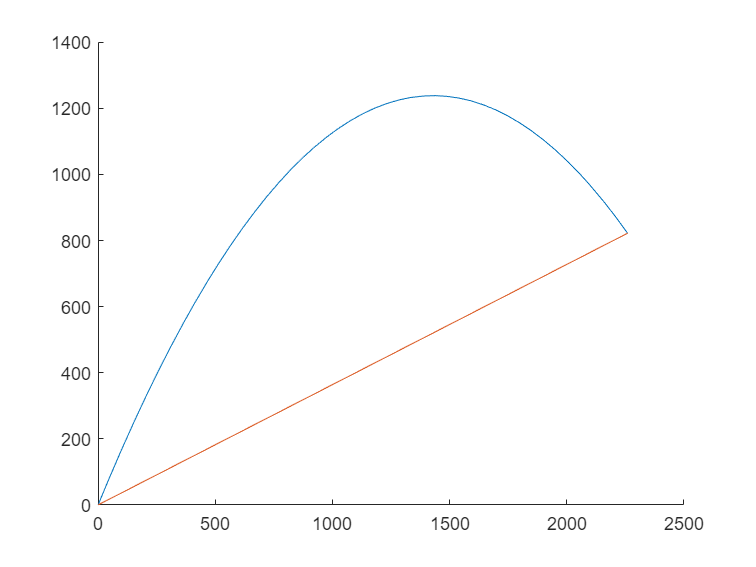

clear all;
syms x;
v_0 = 180;
theta = deg2rad(60);
g = 9.81;
v_x = v_0 * cos(theta);
v_y = v_0 * sin(theta);
forskrift = vpa(v_y * (x/v_x) - 0.5 * g * (x/v_x)^2, 3);
clf('reset')
y = v_y * (x/v_x) - 0.5 * g * (x/v_x)^2;
y_x = x * tand(20);
afstand = vpasolve(y == y_x,x);
t = afstand(2)/v_x;
y_t = v_y * t - 0.5 * g * t^2;
hold on
fplot(y,[0 2259.2156])
fplot(y_x,[0 2259.2156])
hold off

## C) Afstanden R

Afstand R kan nu findes gennem pytagoras grundet de fundende størrelser: y_t & krydsningen mellem bakke og afstandsformelen:

- 
$$R = \sqrt{1078.91^2 + 369.01^2} = 1140.27 m$$


R = vpa(sqrt(afstand(2)^2 + y_t^2),6)

$$R = 2404.21$$

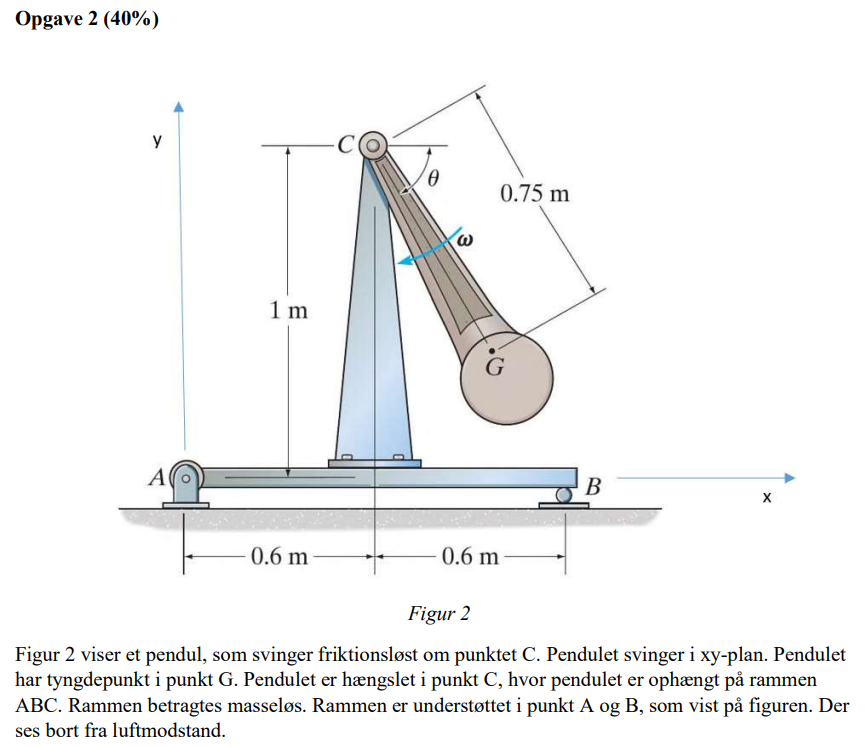

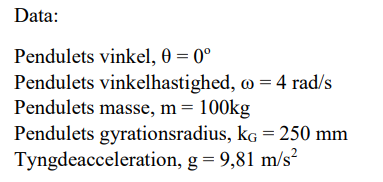

theta = deg2rad(0);
omega = 4;
m = 100;
k_G = 0.25;
g = 9.81;

## A) Pendulets masseinertimoment om pendulets tyngdepunkt, IG 

Pendulets masseinertimoment kan bestemmes på baggrund af pendulet gyrationsradius:

- 
$$I_G = k_G^2 \cdot m = (0.25m)^2 * 100 kg = 6.25 kg \cdot m^2$$


I_G = k_G^2 * m

I_G = 6.2500

## B) Pendulets masseinertimoment om pendulets hængslede ende, IC

Pendulets masseinertimoment om pendulets hængslede ende $I_C$ kan findes ved:

- 
$$I_C = I_G + m \cdot d^2 = 62.5 kg \cdot m^2$$


Over d = 0.75m

d = 0.75;
I_C = I_G + m * d^2

I_C = 62.5000

## C) Frit legeme diagram for pendulet

## D) Kinetisk diagram for pendulet

## E) Pendulets vinkelacceleration, α

Pendulets vinkelacceleration kan bestemmes ved følgende sætning:

- 
$$\sum M_C = I_C \cdot \alpha : m \cdot g \cdot d = I_C \cdot \alpha \rightarrow \alpha = \frac{m \cdot g \cdot d}{I_C} = 11.772 \frac{rads}{s^2} $$
  

alpha = (m * g *d)/I_C

alpha = 11.7720

## F) Reaktionskræfterne Cx og Cy, i punkt C

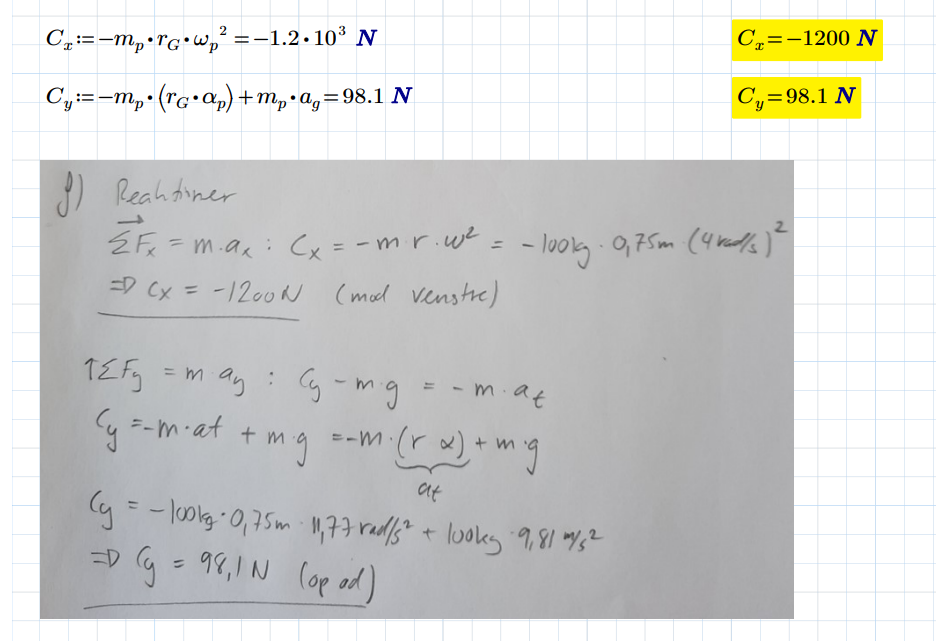

## G) Rammens reaktionskræfter i punkt A og B

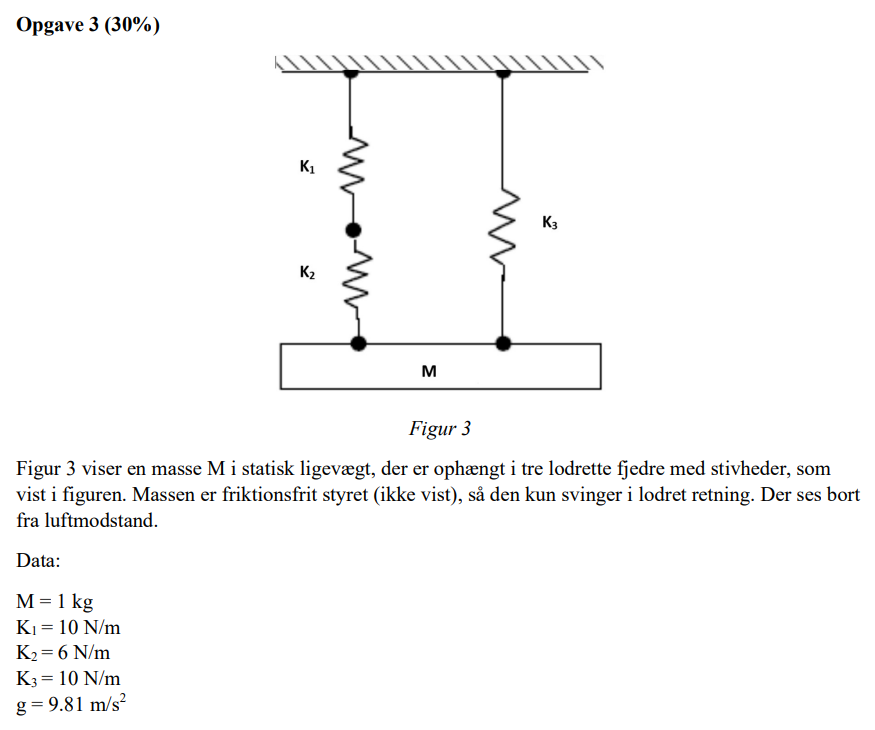

## A) Den cykliske egenfrekvens $\omega_1$ (svaret ønskes anført i både rad/s og omdr./min) 

Egenfrekvensen er angivet som:

- 
$$\omega_n = \sqrt{\frac{k_{eq}}{m}}$$


Heraf er vores $k_{eq}$ en samlet størrelse baseret på en serie og en parallel forbindelse:

- 
$$k_{serie} = \frac{1}{ \frac{1}{k_1} + \frac{1}{k_2} } \rightarrow k_{serie} = \frac{1}{ \frac{1}{10 \frac{N}{m}} + \frac{1}{6 \frac{N}{m}} } = 3.75 \frac{N}{m}$$
 

- 
$$k_{eq} = k_{serie} + k_3 = 13.75 \frac{N}{m}$$


k_1 = 10;
k_2 = 6;
k_3 = 10;
m = 1;
g = 9.81;

k_serie = 1/( (1/k_1) + (1/k_2) )

k_serie = 3.7500

k_eq = k_serie + k_3

k_eq = 13.7500

Hvoraf vores egenfrekvens bliver:

- 
$$\omega_n = \sqrt{\frac{k_{eq}}{m}} = 3.7081 \frac{rads}{s}$$


- 
$$\omega_{n_{RPM}} = \frac{60 \cdot \sqrt{\frac{k}{m}}}{2 \cdot \pi} = 35.4097 \frac{omdr.}{min}$$


omega_n = sqrt(k_eq/m)

omega_n = 3.7081

RPM = (60*omega_n)/(2*pi)

RPM = 35.4097

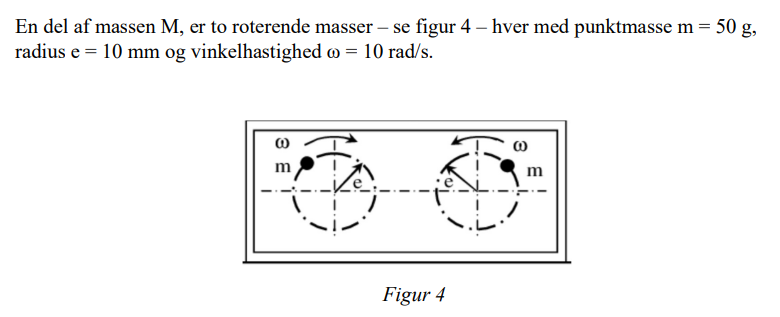

## B) Forskriften for den lodrette kraftkomposant FL(t) af kraftpåvirkningen fra de to roterende  masser 

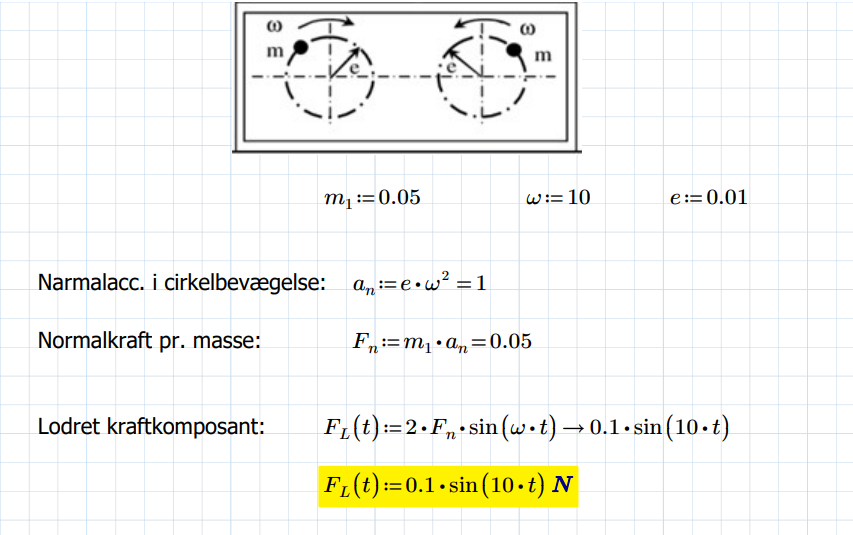

## C) Lordret kraftkomposant når $\omega = \omega_1$